# **Vehicle Performance Analysis (CoDPAD M1-1)**

**CoDPAD module 1 : Vehicle performance analysis - Metadata extraction**

본 장에서는 refSigTest를 통한 비행시험에서 얻어진 데이터를 기반으로, 기체의 기본성능 분석을 위한 메타데이터(전달함수, 분산특성, 확률변수 등)를 추출하는 것을 목표로 한다. 사용자의 선택에 따라 비행 state 데이터를 분류하여 전달함수를 구하거나, 특정 시험의 state를 그래프로 시각화할 수 있다. 자세한 사항은 아래 링크 참조.

[CoDPAD Ch1.1 - Confluence](https://nearth.atlassian.net/l/c/jtPt190P)

[CoDPAD Ch. 1.2 - Confluence](https://nearth.atlassian.net/l/c/3fbf1ss9)

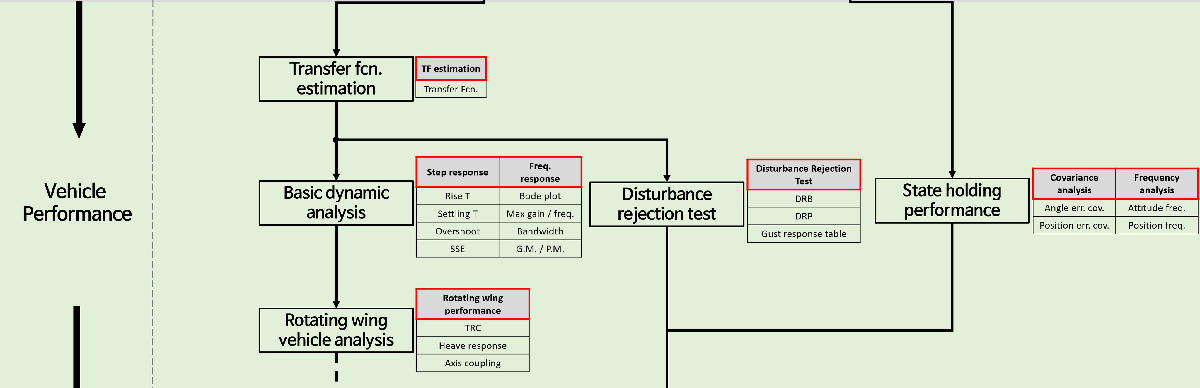

**Appendix : Sweep Signal Equation**

#### 
$$\theta(t) = \omega_{min}t + c_2(\omega_{max}-\omega_{min})({T\over c_{min}}*e^{{c_1\over T}*t}-t) - res$$


global nN nD
cd(fileparts(matlab.desktop.editor.getActiveFilename))


## Basic parameters

#### **index guide**

1 : roll step test

2 : v step test

3 : Y step test

4 : pitch step test

5 : u step test

6 : X step test

7 : yaw step test

8 : w step test

9 : Z step test

#### **User Input**

specify this script's mode of operation (to plot or to estimate tf), missionIdx of interest, and the address of gdLogFile.

doplot = 1 

doplot = 1

includeSweep = false

includeSweep = logical
   0



missionIdxToPlot = 11

missionIdxToPlot = 11

gdLogFile = "gdLog_210702_110357.csv"

gdLogFile = "gdLog_210702_110357.csv"

Fs = 50

Fs = 50


% Transfer function params
nN = 1;
nD = 2;

% DO NOT CHANGE _ params.
c1 = 4; c2 = 0.01866;
wmin = 0.4*2*pi;
wmax = 10*2*pi;
T = 20;
d2r = pi/180;
r2d = 1/d2r;

## Load data

Loading data from the specified gdLogFile at interest.

% [data, data_time] = loader(gdLogFile);
% data_time = seconds(data_time);

% data = readtable(gdLogFile);
data = load('/home/jaehan/Desktop/MATLAB devel/NLP/systemIDData.mat');
data = data.data;
data_time = data.rosTime;
data_time = seconds(data_time);
data_time = data_time - data_time(1);
dataSize = size(data,1);

%% Coodinate adjustment
posNed = [data.posNED_m_0,data.posNED_m_1,data.posNED_m_2];
posNedCmd = [data.posCmdNED_m_0,data.posCmdNED_m_1,data.posCmdNED_m_2];
velNed = [data.velNED_mps_0,data.velNED_mps_1,data.velNED_mps_2];
velNedCmd = [data.velCmdHdg_mps_0,data.velCmdHdg_mps_1,data.velCmdHdg_mps_2];
att = [data.rpy_deg_0,data.rpy_deg_1,data.rpy_deg_2];
attCmd = [data.rpdCmd_deg_deg_mps_0,data.rpdCmd_deg_deg_mps_1,data.yawSp_deg];
gimbalAtt = [data.gimbalRpy_deg_0,data.gimbalRpy_deg_1,data.gimbalRpy_deg_2];
gimbalAttCmd = [data.gimbalRpyCmd_deg_0,data.gimbalRpyCmd_deg_1,data.gimbalRpyCmd_deg_2];
pqr = [data.pqr_dps_0,data.pqr_dps_1,data.pqr_dps_2];

dcmI2body = angle2dcm(wrapToPi(data.rpy_deg_2*d2r), zeros(size(data,1),1), zeros(size(data,1),1),'zyx');

posXyz = zeros(size(posNed));
posXyzCmd = zeros(size(posNed));
velUvw = zeros(size(posNed));
velUvwCmd = velNedCmd;
posXyzCmd = posNedCmd;
posXyz = posNed;
for i = 1:size(posNed,1)
    posXyz(i,:) = dcmI2body(:,:,i) * posNed(i,:)';
    posXyzCmd(i,:) = dcmI2body(:,:,i) * posNedCmd(i,:)';
    velUvw(i,:) = dcmI2body(:,:,i) * velNed(i,:)';
end

posXyz_0 = posXyz(:,1);
posXyz_1 = posXyz(:,2);
posXyz_2 = posXyz(:,3);
posXyzCmd_0 = posXyzCmd(:,1);
posXyzCmd_1 = posXyzCmd(:,2);
posXyzCmd_2 = posXyzCmd(:,3);
velUvw_0 = velUvw(:,1);
velUvw_1 = velUvw(:,2);
velUvw_2 = velUvw(:,3);
velUvwCmd_0 = velUvwCmd(:,1);
velUvwCmd_1 = velUvwCmd(:,2);
velUvwCmd_2 = velUvwCmd(:,3);

% gimbalAtt = rand(dataSize,3)/5 + velUvw/4; %% erase!
data_essential = [pqr,att,velUvw,posXyz,gimbalAtt];


## Data parsing

'refSigTest' consists of total 7 missions. (3 step tests, 3 sweep test, 1 hold test) Step test and sweep test consist of 3 subjobs each. Holding test consists of 2 subjobs.  This part parses whole gdLogdata into individual test sets (each subjobs). Refer to CoDPAD document Ch. 1-1 for more details.

[https://nearth.atlassian.net/l/c/hQRhdouM](https://nearth.atlassian.net/l/c/hQRhdouM)

testStartFlag = [];
testFinishFlag = [];
missionStartFlag = [];
missionFinishFlag = [];
fcMode = data.fcMcMode;
missionType = data.missionType;

ns = 1; nf = 1; nsm = 1; nfm = 1;
for i = 2:length(fcMode)
    if fcMode(i) ~= fcMode(i-1) && fcMode(i) == 2
        testStartFlag(ns) = i; ns = ns+1;
    elseif fcMode(i) ~= fcMode(i-1) && fcMode(i-1) == 2
        testFinishFlag(nf) = i; nf = nf+1;
    end
    if fcMode(i-1) == 0 && fcMode(i) == 1
        missionStartFlag(nsm) = i; nsm = nsm + 1;
    elseif fcMode(i-1) == 1 && fcMode(i) == 0
        missionFinishFlag(nfm) = i; nfm = nfm + 1;
    end
end

responseSet = [data.rpy_deg_0*d2r,velUvw_1,posXyz_1,data.rpy_deg_1*d2r,velUvw_0,posXyz_0,data.rpy_deg_2*d2r,velUvw_2,posXyz_2];
cmdSet = [data.rpdCmd_deg_deg_mps_0*d2r,velUvwCmd_1,posXyzCmd_1,data.rpdCmd_deg_deg_mps_1*d2r,velUvwCmd_0,posXyzCmd_0,data.yawSp_deg*d2r,velUvwCmd_2,posXyzCmd_2];

gimbaldev = sqrt((data.gimbalRpy_deg_0*d2r).^2 + (data.gimbalRpy_deg_1*d2r).^2 + (data.gimbalRpy_deg_2*d2r).^2);

n = missionIdxToPlot; % Select test index

m = n;
if m > 9
    m = m-9;
end
Cmd = cmdSet(testStartFlag(n):testFinishFlag(n)-1,m);
time = data_time(testStartFlag(n):testFinishFlag(n)-1);
response = responseSet(testStartFlag(n):testFinishFlag(n)-1,m);



## **Transfer Function Estimation**

This part estimates transfer function for each test sets. The results are saved in struct "tfResult".

if doplot == 1
    %% TF estimation - use as required
    
    % Basic TF - All (Step & Sweep) - NOT USED AT THE MOMENT
%     tfResult = {};
%     for i = 1:18
%         [Num,Den,delay]=estimate_tf(i,i,responseSet,cmdSet,testStartFlag,testFinishFlag);
%         tfResult{i}.Num = Num;
%         tfResult{i}.Den = Den;
%         tfResult{i}.Delay = delay;
%         A = [num2str(i),'th transfer function estimation complete'];
%         disp(A)
%         tfResult{i}
%     end
    
    % Basic TF - (Step test only)
    tfResult = {};
    for i = 1:9
        [Num,Den,delay]=estimate_tf(i,i,responseSet,cmdSet,testStartFlag,testFinishFlag);
        tfResult{i}.Num = Num;
        tfResult{i}.Den = Den;
        tfResult{i}.Delay = delay;
        A = [num2str(i),'th transfer function estimation complete'];
        disp(A)
        sys = tf(tfResult{i}.Num,tfResult{i}.Den,'ioDelay',tfResult{i}.Delay)
    end
    
    % Mix TF - EXPERIMENTAL - NOT USED AT THE MOMENT
    % tfResult_mix = {};
    % for i = 1:3
    %     [Num,Den,delay]=estimate_tf(3,i,responseSet,cmdSet,testStartFlag,testFinishFlag);
    %     tfResult_mix{i}.Num = Num;
    %     tfResult_mix{i}.Den = Den;
    %     tfResult_mix{i}.Delay = delay;
    %     A = [num2str(i),'th transfer function estimation complete'];
    %     disp(A)
    % end
    
    %% Sweep signal
    % res = c2*(wmax-wmin)*T/c1;
    % omega = wmin + (exp((time-time(1))/T*c1)-1)*c2*(wmax-wmin);
    % freq = omega/2/pi;
    % theta = wmin*t + c2*(wmax-wmin)*(T/c1*exp(c1/T*t)-t) - res;
    save('tfResult.mat','tfResult')
end

1th transfer function estimation complete


sys =
 
                   0.4717 s + 284.9
  exp(-0.04*s) * ---------------------
                 s^2 + 16.59 s + 300.3
 
Continuous-time transfer function.



2th transfer function estimation complete


sys =
 
                   3.596 s + 8.573
  exp(-0.1*s) * ---------------------
                s^2 + 4.276 s + 8.346
 
Continuous-time transfer function.



3th transfer function estimation complete


sys =
 
                   0.1533 s + 1.345
  exp(-0.28*s) * --------------------
                 s^2 + 2.012 s + 1.37
 
Continuous-time transfer function.



4th transfer function estimation complete


sys =
 
                   10.26 s + 48.43
  exp(-0.1*s) * ---------------------
                s^2 + 10.41 s + 57.71
 
Continuous-time transfer function.



5th transfer function estimation complete


sys =
 
                   37.05 s + 84.47
  exp(-0.42*s) * --------------------
                 s^2 + 30.67 s + 85.3
 
Continuous-time transfer function.



6th transfer function estimation complete


sys =
 
                    0.5291 s + 1.27
  exp(-0.46*s) * ---------------------
                 s^2 + 2.073 s + 1.283
 
Continuous-time transfer function.



7th transfer function estimation complete


sys =
 
                   -0.6099 s + 27.14
  exp(-0.06*s) * ---------------------
                 s^2 + 6.542 s + 27.26
 
Continuous-time transfer function.



8th transfer function estimation complete


sys =
 
                   0.6969 s + 15.31
  exp(-0.06*s) * ---------------------
                 s^2 + 4.483 s + 15.42
 
Continuous-time transfer function.



9th transfer function estimation complete


sys =
 
                   0.6375 s + 3.542
  exp(-0.26*s) * ---------------------
                 s^2 + 2.887 s + 3.511
 
Continuous-time transfer function.



## Plotting

if doplot == 1


### **Vehicle Attitude Response (rpy)**

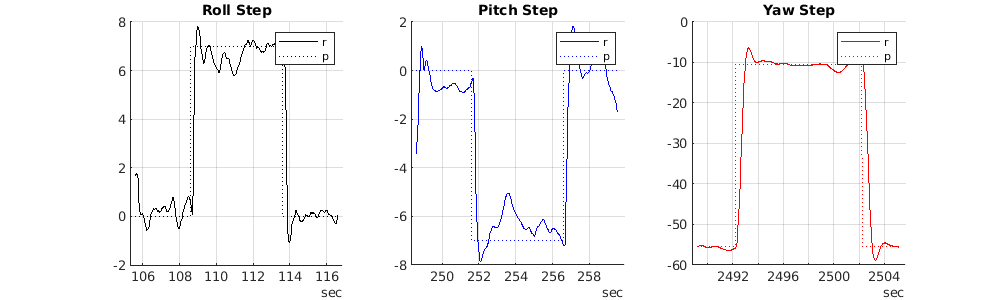

figure(10)
clf
subplot(1,3,1)
range = testStartFlag(1):testFinishFlag(1)-1;
hold on
grid on
plot(data_time(range),data.rpy_deg_0(range),'k')
plot(data_time(range),data.rpdCmd_deg_deg_mps_0(range),'k:')
title('Roll Step')
legend('r','p','y')
subplot(1,3,2)
range = testStartFlag(4):testFinishFlag(4)-1;
hold on
grid on
plot(data_time(range),data.rpy_deg_1(range),'b')
plot(data_time(range),data.rpdCmd_deg_deg_mps_1(range),'b:')
title('Pitch Step')
legend('r','p','y')
subplot(1,3,3)
range = testStartFlag(7):testFinishFlag(7)-1;
hold on
grid on
plot(data_time(range),data.rpy_deg_2(range),'r')
plot(data_time(range),data.yawSp_deg(range),'r:')
title('Yaw Step')
legend('r','p','y')
set(gcf,'Position',[10 10 1000 300])

### **Vehicle Velocity Response (uvw)**

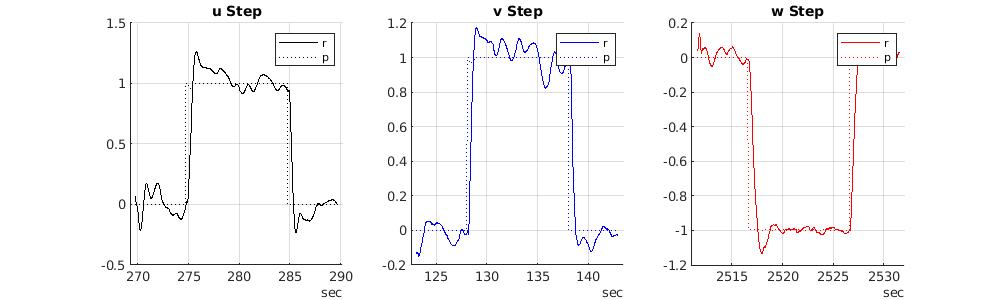

figure(11)
clf
subplot(1,3,1)
range = testStartFlag(5):testFinishFlag(5)-1;
hold on
grid on
plot(data_time(range),data.velUVW_mps_0(range),'k')
plot(data_time(range),data.velCmdUVW_mps_0(range),'k:')
title('u Step')
legend('r','p','y')
subplot(1,3,2)
range = testStartFlag(2):testFinishFlag(2)-1;
hold on
grid on
plot(data_time(range),data.velUVW_mps_1(range),'b')
plot(data_time(range),data.velCmdUVW_mps_1(range),'b:')
title('v Step')
legend('r','p','y')
subplot(1,3,3)
range = testStartFlag(8):testFinishFlag(8)-1;
hold on
grid on
plot(data_time(range),data.velUVW_mps_2(range),'r')
plot(data_time(range),data.velCmdUVW_mps_2(range),'r:')
title('w Step')
legend('r','p','y')
set(gcf,'Position',[10 10 1000 300])

### **Vehicle Position Response (XYZ)**

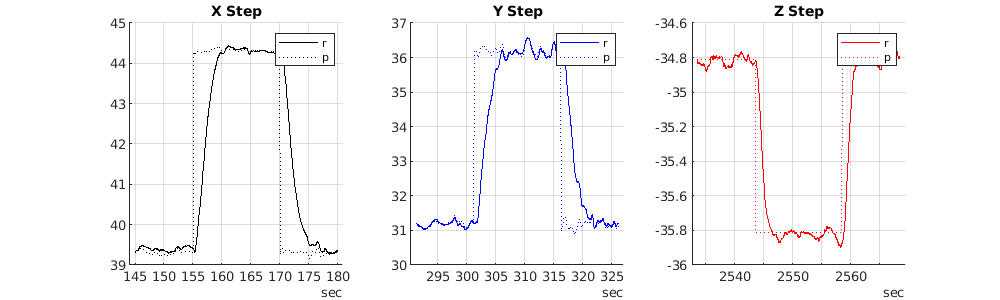

figure(12)
clf
subplot(1,3,1)
range = testStartFlag(3):testFinishFlag(3)-1;
hold on
grid on
plot(data_time(range),posXyz_1(range),'k')
plot(data_time(range),posXyzCmd_1(range),'k:')
title('X Step')
legend('r','p','y')
subplot(1,3,2)
range = testStartFlag(6):testFinishFlag(6)-1;
hold on
grid on
plot(data_time(range),posXyz_0(range),'b')
plot(data_time(range),posXyzCmd_0(range),'b:')
title('Y Step')
legend('r','p','y')
subplot(1,3,3)
range = testStartFlag(9):testFinishFlag(9)-1;
hold on
grid on
plot(data_time(range),posXyz_2(range),'r')
plot(data_time(range),posXyzCmd_2(range),'r:')
title('Z Step')
legend('r','p','y')
set(gcf,'Position',[10 10 1000 300])

### **Gimbal Response (Steady Test)**

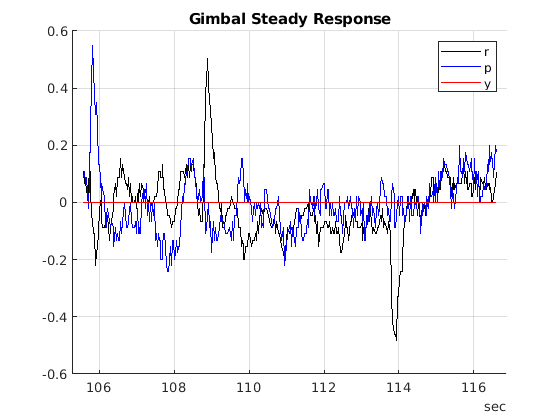

figure(13)
clf
range = testStartFlag(1):testFinishFlag(1)-1;
hold on
grid on
plot(data_time(range),gimbalAtt(range,1),'k')
plot(data_time(range),gimbalAtt(range,2),'b')
plot(data_time(range),gimbalAtt(range,3),'r')
title('Gimbal Steady Response')
legend('r','p','y')

end

## Additional Data Extraction (for further analysis)

This part extracts additional data that is required for the following chapter's analysis.

% Heave response tf estimation
nN = 0; nD = 1;
[Num,Den,delay] = estimate_tf(8,8,responseSet,cmdSet,testStartFlag,testFinishFlag);
heaveTfResult = {};
heaveTfResult.Num = Num;
heaveTfResult.Den = Den;
heaveTfResult.Delay = delay;
save('heaveTf.mat','heaveTfResult');

% Steady dataset covariance calculation
covResult = {};
posSteadyIdx = 10; %%TODO to 19
velSteadyIdx = 11; %%TODO to 20

posHoldRange = testStartFlag(posSteadyIdx):testFinishFlag(posSteadyIdx)-1;
velHoldRange = testStartFlag(velSteadyIdx):testFinishFlag(velSteadyIdx)-1;
if mod(length(posHoldRange),2) == 1
    posHoldRange(end) = [];
end
if mod(length(velHoldRange),2) == 1
    velHoldRange(end) = [];
end

% de-biasing
data_essential(posHoldRange,6) = data_essential(posHoldRange,6) - data.yawSp_deg(posHoldRange);
data_essential(velHoldRange,6) = data_essential(velHoldRange,6) - data.yawSp_deg(velHoldRange);

posHoldCov = cov(data_essential(posHoldRange,:));
posHoldMean = mean(data_essential(posHoldRange,:));
posHoldStd = std(data_essential(posHoldRange,:));
velHoldCov = cov(data_essential(velHoldRange,:));
velHoldMean = mean(data_essential(velHoldRange,:));
velHoldStd = std(data_essential(velHoldRange,:));

for i = 1:size(data_essential,2)
    [freq, fftResult, psdResult] = data2fftpsd(data_essential(posHoldRange,i),Fs);
    covResult.posHoldFreq{i}.freq = freq;
    covResult.posHoldFreq{i}.fft = fftResult;
    covResult.posHoldFreq{i}.psd = psdResult;
    
    [freq, fftResult, psdResult] = data2fftpsd(data_essential(velHoldRange,i),Fs);
    covResult.velHoldFreq{i}.freq = freq;
    covResult.velHoldFreq{i}.fft = fftResult;
    covResult.velHoldFreq{i}.psd = psdResult;
end

covResult.pos = posHoldCov;
covResult.vel = velHoldCov;
covResult.posHoldMean = posHoldMean;
covResult.velHoldMean = velHoldMean;
covResult.posHoldStd = posHoldStd;
covResult.velHoldStd = velHoldStd;

save('covResult.mat','covResult');

% Cross-data transfer function estimation
% TODO

% vehicle - gimbal transfer function estimation
gvResult = {};
if includeSweep
    nN = 1; nD = 2;
    for i = 1:3
        [Num,Den,delay] = estimate_tf(1,i,gimbalAtt,cmdSet,testStartFlag,testFinishFlag);
        gvResult{i}.Num = Num;
        gvResult{i}.Den = Den;
        gvResult{i}.Delay = delay;
    end
end

save('gvResult.mat','gvResult');


## Fcn definition - for transfer function estimation

This part shows the function that estimates the transfer function based on the data acquired from flight test. This part requires 'system ID toolbox'.

function [Num, Den, delay] = estimate_tf(n,mix,responseSet,cmdSet,testStartFlag,testFinishFlag)
global nN  nD
m = n;
if n>9
    m = n-9;
end
if mix>9
    mix = mix-9;
end
Cmd = cmdSet(testStartFlag(n):testFinishFlag(n)-1,m);
Response = responseSet(testStartFlag(n):testFinishFlag(n)-1,m);
if mix ~= m
    Response = responseSet(testStartFlag(n):testFinishFlag(n)-1,mix);
end
Cmd = detrend(Cmd,0);
Response = detrend(Response,0);

timeseriesSet = iddata(Response,Cmd,0.02);
sys = tfest(timeseriesSet,nD,nN,nan);
Num = sys.Numerator;
Den = sys.Denominator;
delay = sys.IODelay;
end